# Adding Sensor Fault to Raw Structure Response

load workspace_b.mat

## 1 Sensor Fault Simulation

Data_Fault = []; % Data with Sensor Fault
for i = 1:NumSeg % # of window
    for j = 1:nDOF % # of DOF
        for m = 1:NumEventType % event
            for n = 1:NumFaultType % sensor fault
                if n == 1
                    Data_Fault(i,j,m,n,:) = squeeze(Data_Raw(i,j,m,:));
                elseif n == 2
                    Data_Fault(i,j,m,n,:) = add_bias(squeeze(Data_Raw(i,j,m,:)),bias_lb,bias_ub);
                elseif n == 3
                    Data_Fault(i,j,m,n,:) = add_drift(squeeze(Data_Raw(i,j,m,:)),k_cap,SimStep);
                else
                    Data_Fault(i,j,m,n,:) = add_spike(squeeze(Data_Raw(i,j,m,:)),spike_lb,spike_ub);
                end
            end
        end
    end
end

fn_tmp = 'Data_Fault.mat';
save(fn_tmp,'Data_Fault')  

## 2 Visualization

indi = randi(NumSeg)

indi = 5

indj = randi(nDOF)

indj = 5

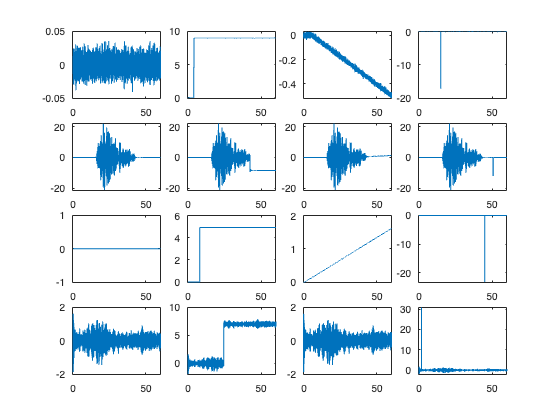


% plot
for m = 1:NumEventType
    for n = 1:NumFaultType
        %disp((m-1)*NumFaultType+n)
        subplot(NumEventType,NumFaultType,(m-1)*NumFaultType + n)
        plot(TimeSeries,squeeze(Data_Fault(indi,indj,m,n,:)))
    end
end

save workspace_c.mat